clear;
clc;
close all;

env = MultiAgentPatientHealthEnv;

try
    validateEnvironment(env);
catch ME
    error('Environment validation failed. Please ensure the environment is correctly defined.\n%s', ME.message);
end

dqn_agent_files = {
    'agent1_Trained.mat', 'agent2_Trained.mat', 'agent3_Trained.mat', 'agent4_Trained.mat', ...
    'agent1_Trained_1.mat', 'agent2_Trained_1.mat', 'agent3_Trained_1.mat', 'agent4_Trained_1.mat', ...
    'agent1_Trained_2.mat', 'agent2_Trained_2.mat', 'agent3_Trained_2.mat', 'agent4_Trained_2.mat'
};

ppo_agent_files = {
    'agent1_ppo_Trained.mat', 'agent2_ppo_Trained.mat', 'agent3_ppo_Trained.mat', 'agent4_ppo_Trained.mat', ...
    'agent1_ppo_Trained_1.mat', 'agent2_ppo_Trained_1.mat', 'agent3_ppo_Trained_1.mat', 'agent4_ppo_Trained_1.mat', ...
    'agent1_ppo_Trained_2.mat', 'agent2_ppo_Trained_2.mat', 'agent3_ppo_Trained_2.mat', 'agent4_ppo_Trained_2.mat'
};

num_episodes = 1;

% DQN Metrics
dqn_total_rewards = [];
dqn_average_rewards = [];
dqn_max_rewards = [];
dqn_min_rewards = [];
dqn_success_rates = [];
dqn_average_entropy = [];
dqn_smoothed_rewards = [];

% PPO Metrics
ppo_total_rewards = [];
ppo_average_rewards = [];
ppo_max_rewards = [];
ppo_min_rewards = [];
ppo_success_rates = [];
ppo_average_entropy = [];
ppo_smoothed_rewards = [];

success_threshold = 100;
window_size = 10;

figure_smoothed = figure('Name', 'Smoothed Rewards');
figure_total = figure('Name', 'Total Rewards');
figure_success = figure('Name', 'Success Rates');
figure_entropy = figure('Name', 'Average Entropy');

calculate_entropy = @(probabilities) -sum(probabilities .* log(probabilities), 2);

% Ensure there is no existing parallel pool before creating a new one
pool = gcp('nocreate');  % Check if a parallel pool is already open
if ~isempty(pool)
    delete(pool);  % Delete existing parallel pool if it exists
end

Parallel pool using the 'Processes' profile is shutting down.



% Now create a new parallel pool
parpool('Processes', 4);  % Create a new parallel pool with 4 workers

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


dqn_metrics = [];  % Empty array to hold DQN metrics
ppo_metrics = [];  % Empty array to hold PPO metrics

function metrics = evaluate_agents(agent_files, env, num_episodes, success_threshold, calculate_entropy,window_size)
    % Initialize storage for metrics
    metrics = struct('agent_name', {}, ...
                     'total_rewards', {}, ...
                     'average_reward', {}, ...
                     'max_reward', {}, ...
                     'min_reward', {}, ...
                     'success_rate', {}, ...
                     'average_entropy', {}, ...
                     'smoothed_rewards', {});
    hWaitbar = waitbar(0, 'Evaluating Agents...', 'Name', 'DQN Agent Evaluation');

 
    
    parfor i = 1:length(agent_files)
        % Load the agent file
        agent_file = agent_files{i};
        if ~isfile(agent_file)
            warning('File %s does not exist. Skipping.', agent_file);
            continue;
        end
        
        agent_data = load(agent_file);
        
        % Find the agent variable in the file
        agent_vars = fieldnames(agent_data);
        % Exclude any built-in fields
        agent_vars = setdiff(agent_vars, {'__header__', '__version__', '__globals__'});
        if isempty(agent_vars)
            warning('No agent variable found in %s. Skipping.', agent_file);
            continue;
        end
        % Assume the first variable is the agent
        agent_varname = agent_vars{1};
        agent = agent_data.(agent_varname);
        
        % Simulate the agent in the environment
        rewards = zeros(num_episodes, 1);
        entropy_values = [];
        for ep = 1:num_episodes
            % Reset the environment at the start of each episode
            try
                obs = reset(env);
            catch ME
                warning('Failed to reset environment for agent %s: %s', agent_file, ME.message);
                break;
            end
            is_done = false;
            total_reward = 0;
            while ~is_done
                % Get the action from the agent
                try
                    action = getAction(agent, obs);
                catch ME
                    warning('Failed to get action for agent %s: %s', agent_file, ME.message);
                    is_done = true;
                    break;
                end
                % Step the environment
                try
                    [next_obs, reward, is_done, ~] = step(env, action);
                catch ME
                    warning('Failed to step environment for agent %s: %s', agent_file, ME.message);
                    is_done = true;
                    break;
                end
                total_reward = total_reward + reward;  % Make sure reward is on the GPU

                % Update observation
                obs = next_obs;
            end
            rewards(ep) = total_reward;
        end
        
        % Compute evaluation metrics
        total_rewards = sum(rewards);
        average_reward = mean(rewards);
        max_reward = max(rewards);
        min_reward = min(rewards);
        success_count = sum(rewards >= success_threshold);
        success_rate = (success_count / length(rewards)) * 100;
        
        % Calculate Entropy (if action probabilities are available)
        if isfield(agent_data, 'action_probabilities')
            action_probs = agent_data.action_probabilities;
            entropy = calculate_entropy(action_probs);
            average_entropy = mean(entropy);
        else
            average_entropy = NaN;  % Not available
        end
        
        % Smooth the rewards
        smoothed_rewards = movmean(rewards, window_size);
        
        % Store the metrics
        metrics(i).agent_name = agent_file;
        metrics(i).total_rewards = total_rewards;
        metrics(i).average_reward = average_reward;
        metrics(i).max_reward = max_reward;
        metrics(i).min_reward = min_reward;
        metrics(i).success_rate = success_rate;
        metrics(i).average_entropy = average_entropy;
        metrics(i).smoothed_rewards = smoothed_rewards;
    end

    close(hWaitbar);
    
end

fprintf('Evaluating DQN Agents...\n');

Evaluating DQN Agents...


dqn_metrics = evaluate_agents(dqn_agent_files, env, num_episodes, success_threshold, calculate_entropy,window_size);

for i = 1:length(dqn_metrics)
    if isempty(dqn_metrics(i).agent_name)
        continue;
    end
    dqn_total_rewards = [dqn_total_rewards; dqn_metrics(i).total_rewards];
    dqn_average_rewards = [dqn_average_rewards; dqn_metrics(i).average_reward];
    dqn_max_rewards = [dqn_max_rewards; dqn_metrics(i).max_reward];
    dqn_min_rewards = [dqn_min_rewards; dqn_metrics(i).min_reward];
    dqn_success_rates = [dqn_success_rates; dqn_metrics(i).success_rate];
    dqn_average_entropy = [dqn_average_entropy; dqn_metrics(i).average_entropy];
    dqn_smoothed_rewards = [dqn_smoothed_rewards; dqn_metrics(i).smoothed_rewards];
end

fprintf('Evaluating PPO Agents...\n');

Evaluating PPO Agents...


ppo_metrics = evaluate_agents(ppo_agent_files, env, num_episodes, success_threshold, calculate_entropy,window_size);

for i = 1:length(ppo_metrics)
    if isempty(ppo_metrics(i).agent_name)
        continue;
    end
    ppo_total_rewards = [ppo_total_rewards; ppo_metrics(i).total_rewards];
    ppo_average_rewards = [ppo_average_rewards; ppo_metrics(i).average_reward];
    ppo_max_rewards = [ppo_max_rewards; ppo_metrics(i).max_reward];
    ppo_min_rewards = [ppo_min_rewards; ppo_metrics(i).min_reward];
    ppo_success_rates = [ppo_success_rates; ppo_metrics(i).success_rate];
    ppo_average_entropy = [ppo_average_entropy; ppo_metrics(i).average_entropy];
    ppo_smoothed_rewards = [ppo_smoothed_rewards; ppo_metrics(i).smoothed_rewards];
end

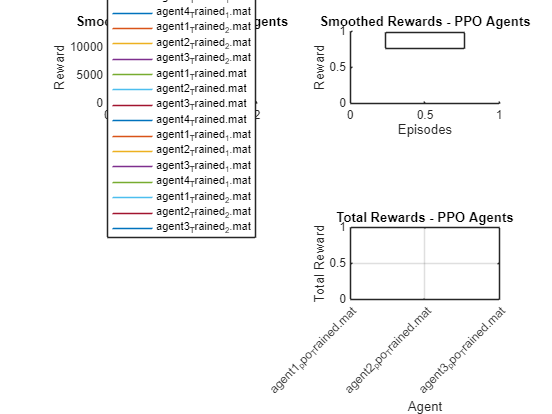

% 1. Plot Smoothed Rewards for DQN Agents
figure(figure_smoothed);
subplot(2,2,1);
hold on;

% Ensure you loop over the available agents and smoothed rewards
num_agents = min(size(dqn_smoothed_rewards, 1), length(dqn_metrics));  % Use the smaller size to avoid out-of-bounds indexing

for i = 1:num_agents
    plot(dqn_smoothed_rewards(i,:), 'DisplayName', dqn_metrics(i).agent_name);
end

title('Smoothed Rewards - DQN Agents');
xlabel('Episodes');
ylabel('Reward');
legend('show', 'Location', 'best');
hold off;

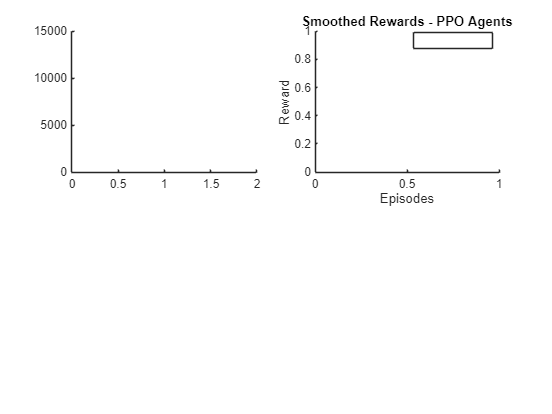

% 2. Plot Smoothed Rewards for PPO Agents
subplot(2,2,2);
hold on;
for i = 1:size(ppo_smoothed_rewards, 1)
    plot(ppo_smoothed_rewards(i,:), 'DisplayName', ppo_metrics(i).agent_name);
end
title('Smoothed Rewards - PPO Agents');
xlabel('Episodes');
ylabel('Reward');
legend('show', 'Location', 'best');
hold off;

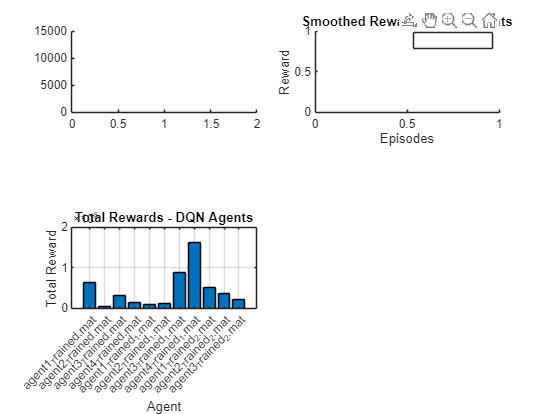

% 3. Plot Total Rewards for DQN Agents
subplot(2,2,3);
bar(dqn_total_rewards);
title('Total Rewards - DQN Agents');
xlabel('Agent');
ylabel('Total Reward');
xticklabels(dqn_agent_files);
xtickangle(45);
grid on;

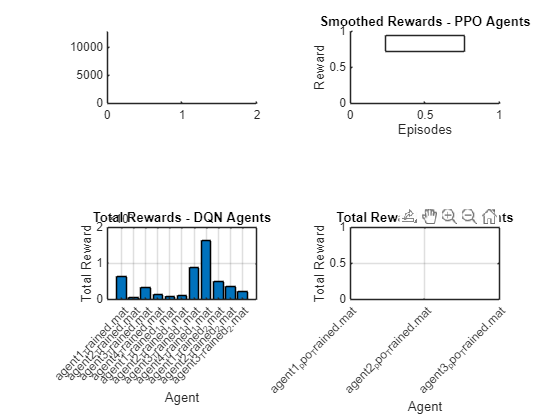

% 4. Plot Total Rewards for PPO Agents
subplot(2,2,4);
bar(ppo_total_rewards);
title('Total Rewards - PPO Agents');
xlabel('Agent');
ylabel('Total Reward');
xticklabels(ppo_agent_files);
xtickangle(45);
grid on;

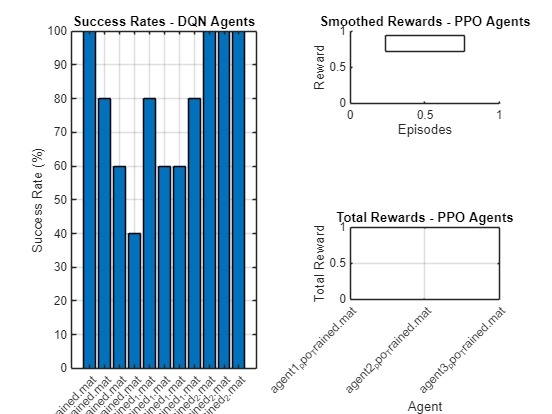

% Create a new figure for Success Rates and Entropy
figure_success;
subplot(1,2,1);
bar(dqn_success_rates);
title('Success Rates - DQN Agents');
xlabel('Agent');
ylabel('Success Rate (%)');
xticklabels(dqn_agent_files);
xtickangle(45);
grid on;

subplot(1,2,2);
bar(ppo_success_rates);
title('Success Rates - PPO Agents');
xlabel('Agent');
ylabel('Success Rate (%)');
xticklabels(ppo_agent_files);
xtickangle(45);
grid on;

if any(~isnan(dqn_average_entropy)) || any(~isnan(ppo_average_entropy))
    figure_entropy;
    subplot(1,2,1);
    bar(dqn_average_entropy);
    title('Average Entropy - DQN Agents');
    xlabel('Agent');
    ylabel('Entropy');
    xticklabels(dqn_agent_files);
    xtickangle(45);
    grid on;
    
    subplot(1,2,2);
    bar(ppo_average_entropy);
    title('Average Entropy - PPO Agents');
    xlabel('Agent');
    ylabel('Entropy');
    xticklabels(ppo_agent_files);
    xtickangle(45);
    grid on;
end

[best_dqn_avg_reward, best_dqn_index] = max(dqn_average_rewards);
best_dqn_agent = dqn_metrics(best_dqn_index);

% 5. Compare Best DQN and PPO Agents
% Find the best DQN agent based on average reward


% Find the best PPO agent based on average reward
[best_ppo_avg_reward, best_ppo_index] = max(ppo_average_rewards);
best_ppo_agent = ppo_metrics(best_ppo_index);

figure('Name', 'Best DQN vs PPO Agent Performance');
hold on;
plot(best_dqn_agent.smoothed_rewards, 'LineWidth', 2, 'DisplayName', ['Best DQN: ' best_dqn_agent.agent_name]);
plot(best_ppo_agent.smoothed_rewards, 'LineWidth', 2, 'DisplayName', ['Best PPO: ' best_ppo_agent.agent_name]);
title('Best DQN vs PPO Agent Performance');
xlabel('Episodes');
ylabel('Smoothed Reward');
legend('show', 'Location', 'best');
hold off;

dqn_table = table();

for i = 1:length(dqn_metrics)
    if isempty(dqn_metrics(i).agent_name)
        continue;
    end
    % Create a temporary table for the current row
    temp_table = table(...
        string(dqn_metrics(i).agent_name), ...  % Convert agent name to string array
        dqn_metrics(i).total_rewards, ...
        dqn_metrics(i).average_reward, ...
        dqn_metrics(i).max_reward, ...
        dqn_metrics(i).min_reward, ...
        dqn_metrics(i).success_rate, ...
        dqn_metrics(i).average_entropy, ...
        'VariableNames', {'AgentName', 'TotalRewards', 'AverageReward', 'MaxReward', 'MinReward', 'SuccessRate', 'AverageEntropy'});
    
    % Append the row to the main table
    dqn_table = [dqn_table; temp_table];
end


writetable(dqn_table, 'dqn_agents_metrics.csv');
disp('DQN evaluation metrics saved to dqn_agents_metrics.csv');

DQN evaluation metrics saved to dqn_agents_metrics.csv


ppo_table = table();
for i = 1:length(ppo_metrics)
    if isempty(ppo_metrics(i).agent_name)
        continue;
    end
    ppo_table = [ppo_table; table(...
        ppo_metrics(i).agent_name, ...
        ppo_metrics(i).total_rewards, ...
        ppo_metrics(i).average_reward, ...
        ppo_metrics(i).max_reward, ...
        ppo_metrics(i).min_reward, ...
        ppo_metrics(i).success_rate, ...
        ppo_metrics(i).average_entropy, ...
        'VariableNames', {'AgentName', 'TotalRewards', 'AverageReward', 'MaxReward', 'MinReward', 'SuccessRate', 'AverageEntropy'})];
end

writetable(ppo_table, 'ppo_agents_metrics.csv');
disp('PPO evaluation metrics saved to ppo_agents_metrics.csv');

fprintf('\n=== DQN Agents Evaluation ===\n');
for i = 1:length(dqn_metrics)
    if isempty(dqn_metrics(i).agent_name)
        continue;
    end
    fprintf('Agent: %s\n', dqn_metrics(i).agent_name);
    fprintf('  Total Rewards: %.2f\n', dqn_metrics(i).total_rewards);
    fprintf('  Average Reward: %.2f\n', dqn_metrics(i).average_reward);
    fprintf('  Max Reward: %.2f\n', dqn_metrics(i).max_reward);
    fprintf('  Min Reward: %.2f\n', dqn_metrics(i).min_reward);
    fprintf('  Success Rate: %.2f%%\n', dqn_metrics(i).success_rate);
    if ~isnan(dqn_metrics(i).average_entropy)
        fprintf('  Average Entropy: %.4f\n', dqn_metrics(i).average_entropy);
    else
        fprintf('  Average Entropy: Not Available\n');
    end
    fprintf('\n');
end

fprintf('=== PPO Agents Evaluation ===\n');
for i = 1:length(ppo_metrics)
    if isempty(ppo_metrics(i).agent_name)
        continue;
    end
    fprintf('Agent: %s\n', ppo_metrics(i).agent_name);
    fprintf('  Total Rewards: %.2f\n', ppo_metrics(i).total_rewards);
    fprintf('  Average Reward: %.2f\n', ppo_metrics(i).average_reward);
    fprintf('  Max Reward: %.2f\n', ppo_metrics(i).max_reward);
    fprintf('  Min Reward: %.2f\n', ppo_metrics(i).min_reward);
    fprintf('  Success Rate: %.2f%%\n', ppo_metrics(i).success_rate);
    if ~isnan(ppo_metrics(i).average_entropy)
        fprintf('  Average Entropy: %.4f\n', ppo_metrics(i).average_entropy);
    else
        fprintf('  Average Entropy: Not Available\n');
    end
    fprintf('\n');
end